ncdisp("A2017335184500.L2_LAC_SST.nc")

Source:
           C:\Users\makarov.rd\Repositories\ms-students\4-geo\A2017335184500.L2_LAC_SST.nc
Format:
           netcdf4
Global Attributes:
           title                         = 'HMODISA Level-2 Data'
           product_name                  = 'A2017335184500.L2_LAC_SST.nc'
           processing_version            = '2014.0.1QL'
           equatorCrossingLongitude      = 115.9148
           orbit_number                  = 82898
           history                       = 'l2gen par=/data2/sdpsoper/vdc/vpu5/workbuf/A2017335184500.L1B_LAC.param metafile=A2017335184500.L2_LAC_SST.nc.meta'
           instrument                    = 'MODIS'
           platform                      = 'Aqua'
           Conventions                   = 'CF-1.6 ACDD-1.3'
           license                       = 'http://science.nasa.gov/earth-science/earth-science-data/data-information-policy/'
           naming_authority              = 'gov.nasa.gsfc.sci.oceandata'
           id                       


sst = ncread("A2017335184500.L2_LAC_SST.nc", 'geophysical_data/sst');
lon = ncread("A2017335184500.L2_LAC_SST.nc", 'navigation_data/longitude');
lat = ncread("A2017335184500.L2_LAC_SST.nc", 'navigation_data/latitude');

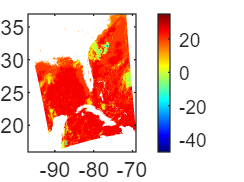

figure();
f1 = contourf(lon,lat,sst,'LineColor','none','LevelStep',5,'');
colorbar
colormap jet

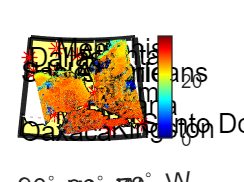

latmax = max(lat,[],'all');
latmin = min(lat,[],'all');
lonmax = max(lon,[],'all');
lonmin = min(lon,[],'all');

land = shaperead('landareas.shp',"UseGeoCoords",true);
cities = shaperead('worldcities.shp',"UseGeoCoords",true);

ax = worldmap([latmin, latmax],[lonmin, lonmax]);
geoshow(ax, land);
geoshow(ax, cities, 'Marker', '*','Tag','on');
geoshow(lat,lon,sst,'DisplayType','surface');
caxis([0 35]);
colormap('jet');
colorbar();
textm([cities.Lat],[cities.Lon],{cities.Name})